# Classifying Traffic Sign Images

In this reading, you will prepare a traffic sign data set for classification and extracting predictor features. 

You will use these features and the Classification Learner App to train and evaluate a model that classifies traffic signs. When you have achieved a model with a test accuracy of at least 90%, you are ready to examine your results with the "Project: Classifying Traffic Sign Images" graded quiz on Coursera.

## Preparing Your Data

Create an image datastore from a folder of traffic signs. Labels are assigned based on the subfolder names, which correspond to the traffic sign type.

Make sure that you navigate to the **"Traffic Signs"** subfolder in the "Data" folder of the course download.

fileName = uigetdir;
imdsSigns = imageDatastore(fileName,"IncludeSubfolders",true,"LabelSource","foldernames");

### Split into Training and Test Sets

Create randomized training and test sets. 80% of the images should be assigned to the training set.

[imdsTrain,imdsTest] = splitEachLabel(imdsSigns,0.8,"randomized");

sum(imdsTrain.Labels == 'Do Not Enter')

ans = 192

## Extracting Predictor Features

Now, use `bagOfFeatures` to create a set of predictor features. You will likely want to revisit this step several times with different parameters to get the best results. You will use these predictor features to train models to classify traffic signs.

For simplicity, we are only using `bagOfFeatures` for this project. However, in applications such as these, you can generally use everything you have learned so far in this course to create a set of predictor features, including hand-selected features, `bagOfFeatures`, or a combination of both. 

Recall that you are trying to create a table with one row for each image, a column for each feature, and an additional column for each image's label.

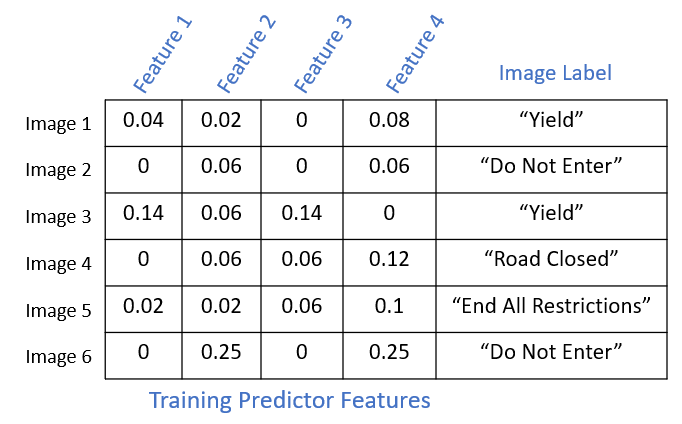

bag = bagOfFeatures(imdsTrain);

predFeats = encode(bag, imdsTrain);
featNames = "f" +string(1:500);
predTable = array2table(predFeats, "VariableNames",featNames);
predTable.labels = categorical(imdsTrain.Labels);

size(testPredTable)

ans =    192   501


Once you are satisfied with your predictor features, you also need to extract features from the test set. Remember to give the features the same names as the features in the training set.

testPredFeats = encode(bag, imdsTest);
testPredTable = array2table(testPredFeats, "VariableNames",featNames);
testPredTable.labels = categorical(imdsTest.Labels);

## Training Models

Train classification models using the Classification Learner App and the predictor features you have just created. Your goal is to train a model with a test accuracy of **at least 90%**.

Make sure you save your Classification Learner App session. You will want to revisit it as you take the graded quiz associated with this project.

*Copyright 2022 The MathWorks, Inc.*